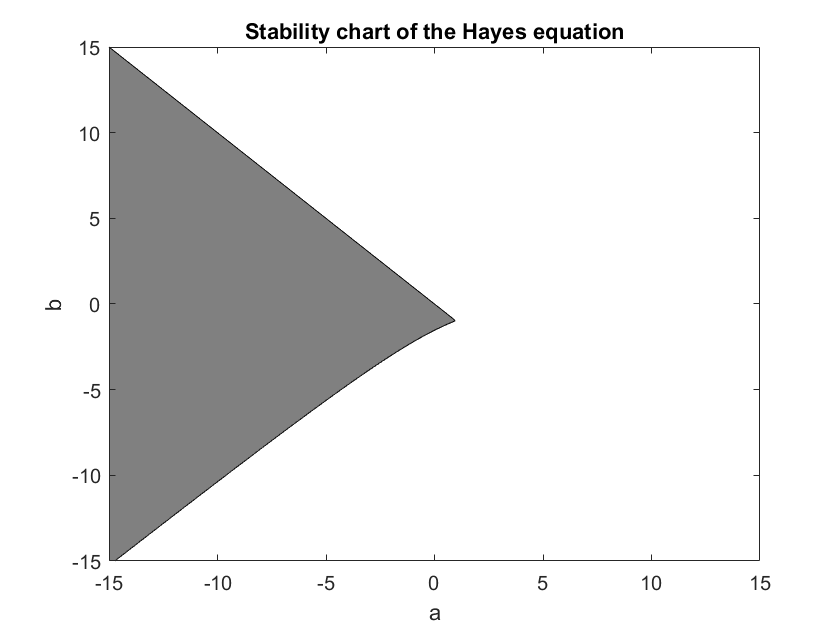

%Semi-discritization for Hayes Equation.
% x'(t)=a*x(t)+b*x(t-tau)

clear all; close all;

tau = 1;
r = 20;
deltat = tau/r;

amin = -15;
amax = 15;
bmin = -15;
bmax = 15;
step = 200;

a_v = linspace(amin,amax,step);
b_v = linspace(bmin,bmax,step);
[a,b] = meshgrid(a_v,b_v); %To expand a and b into matrices
eigcr = zeros(size(a));

%P and R are analytically. See recitation 3, Connected Vehicles
P = exp(a.*deltat);
R = (1./a).*(exp(a.*deltat)-1).*b;

G = zeros(r+1);
G(2:end,1:end-1) = eye(r);

for ka=1:length(a)
    for kb = 1:length(b)
        G(1,1) = P(ka,kb);
        G(1,end) = R(ka,kb);
        eigcr(ka,kb) = max(abs(eig(G)));
    end
end

figure(1); box on;
contourf(a,b,-eigcr,[-1 -1],'k');
colormap gray;
xlabel('a');
ylabel('b');
title('Stability chart of the Hayes equation');